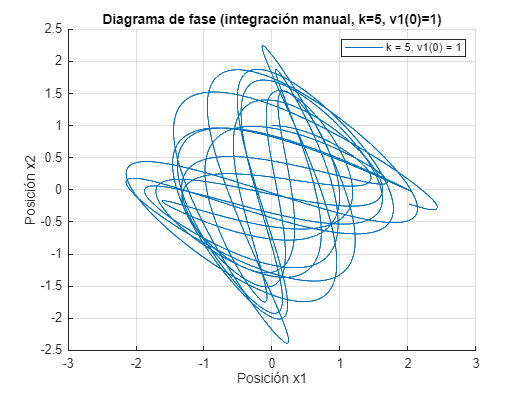

% Parámetros del sistema
m = 1;
eta = 10;  % Fijamos fricción
k = 5;    % Valor fijo de k
v1_0 = 1; % Solo velocidad inicial v1(0) = 1

% Tiempo de simulación
tspan = [0, 100];
dt = 0.01;
N = (tspan(2) - tspan(1)) / dt;
t = linspace(tspan(1), tspan(2), N);

% Figura para el diagrama de fases
figure;
hold on;
grid on;

% Inicialización de variables
x1 = zeros(1, N);
v1 = zeros(1, N);
x2 = zeros(1, N);
v2 = zeros(1, N);

% Condiciones iniciales
x1(1) = 0;
v1(1) = v1_0;
x2(1) = 1;
v2(1) = 0;

% Iteración temporal
for n = 1:N-1
    % Ecuaciones discretizadas (Euler explícito)
    a1 = ( -2 * k * x1(n) + k * x2(n) ) / (m * eta);
    a2 = ( -2 * k * x2(n) + k * x1(n) ) / (m * eta);

    v1(n+1) = v1(n) + a1 * dt;
    x1(n+1) = x1(n) + v1(n) * dt;

    v2(n+1) = v2(n) + a2 * dt;
    x2(n+1) = x2(n) + v2(n) * dt;
end

% Graficar diagrama de fase (x1 vs x2)
plot(x1, x2, 'DisplayName', 'k = 5, v1(0) = 1');

xlabel('Posición x1');
ylabel('Posición x2');
title('Diagrama de fase (integración manual, k=5, v1(0)=1)');
legend show;
grid on;
hold off;

function tau_opt = optimal_tau_mutual_information(x, max_tau, n_bins)

    % Normalizamos la señal
    x = (x - min(x)) / (max(x) - min(x));

    % Inicializar el vector de información mutua
    mutual_info = NaN(1, max_tau);

    % Calcular la información mutua para cada tau
    for tau = 1:max_tau
        x_t = x(1:end - tau);
        x_tau = x(1 + tau:end);

        if length(x_t) < 2 || length(x_tau) < 2
            continue;
        end

        [counts, ~, ~] = histcounts2(x_t, x_tau, n_bins, 'Normalization', 'probability');
        p_joint = counts;

        p_x = sum(p_joint, 2); % columna
        p_y = sum(p_joint, 1); % fila

        epsilon = 1e-12;
        p_joint(p_joint == 0) = epsilon;
        p_x(p_x == 0) = epsilon;
        p_y(p_y == 0) = epsilon;

        p_x = p_x(:);
        p_y = p_y(:)';

        p_prod = p_x * p_y;

        mutual_info(tau) = sum(p_joint(:) .* log2(p_joint(:) ./ p_prod(:)));
    end

    % Encontrar primer mínimo local sin 'findpeaks'
    valid_taus = find(~isnan(mutual_info));
    mi_values = mutual_info(valid_taus);
    tau_candidates = valid_taus;

    tau_opt = tau_candidates(1); % Valor por defecto

    for i = 2:length(mi_values)-1
        if mi_values(i) < mi_values(i-1) && mi_values(i) < mi_values(i+1)
            tau_opt = tau_candidates(i);
            fprintf('Primer mínimo local encontrado: tau = %d\n', tau_opt);
            break;
        end
    end

    % Si no encontró mínimo local, usar mínimo global
    if isempty(tau_opt)
        [~, idx_min] = min(mi_values);
        tau_opt = tau_candidates(idx_min);
        fprintf('No se encontró mínimo local, se usa el mínimo global: tau = %d\n', tau_opt);
    end

    % Visualizar la curva de información mutua
    figure;
    plot(valid_taus, mi_values, 'LineWidth', 1.5);
    hold on;
    plot(tau_opt, mutual_info(tau_opt), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    xlabel('\tau (retardo)');
    ylabel('Información mutua');
    title('Selección de τ óptimo usando primer mínimo de la información mutua');
    grid on;
    hold off;

end

Esta funcion  nos ayuda a descubrir un tau obtimo, el cual no sera muy pequelo, puesto que compartiria mucha informacion x(t) con x(tau+t) en este caso, no puede ser demasiado grande puesto que seria lo contrario en el otro extremo. Para resolver esto se busca en la realción entre tau y la informacion mutua de x(t) y x(tau+t) en primer mínimo local que aparezca.

Primer mínimo local encontrado: tau = 75


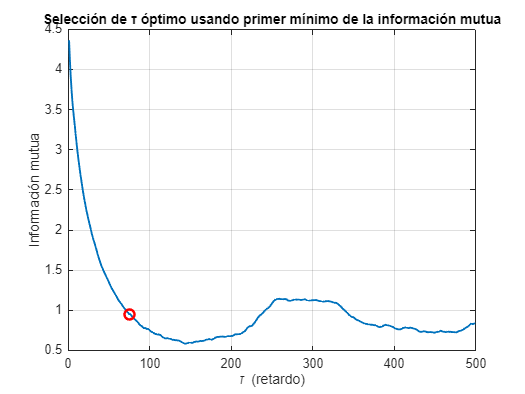




% Suponiendo que quieres probar hasta tau = 500
max_tau = 500;
n_bins = 32; % Número de bins para la discretización (ajustable)

tau_opt = optimal_tau_mutual_information(x1, max_tau, n_bins);

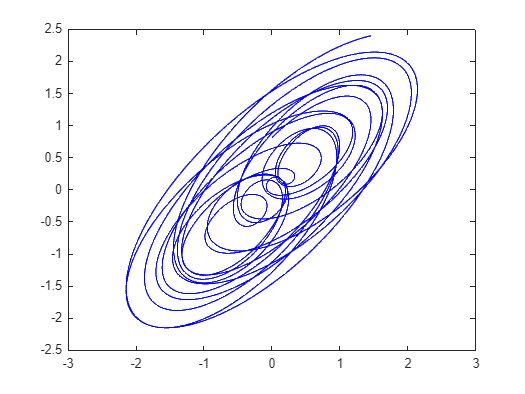



embedding_dim = 3;
X = [];
for i = 1:(N - (embedding_dim - 1) * tau_opt)
    X = [X; x1(i), x1(i + tau_opt), x1(i + 2 * tau_opt)];
end

figure;
plot(X(:,1), X(:,2), 'b');

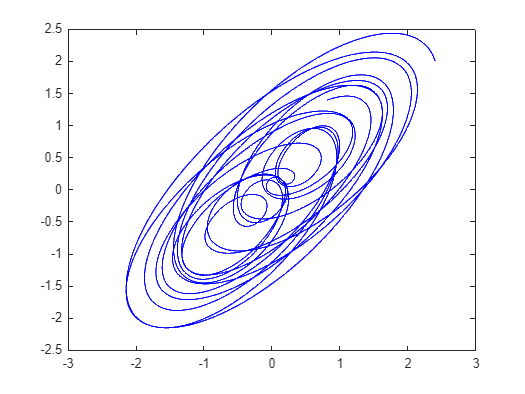

plot(X(:,2), X(:,3), 'b');

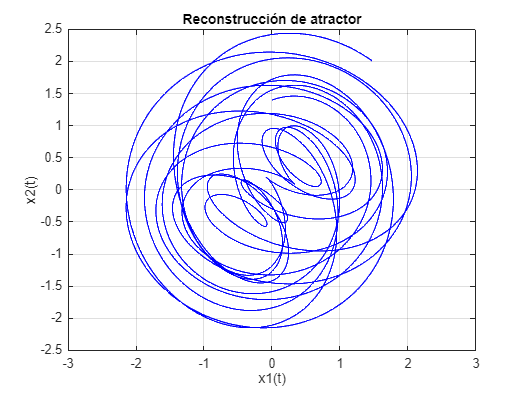

plot(X(:,1), X(:,3), 'b');
xlabel('x1(t)');
ylabel(['x2(t)']);
title('Reconstrucción de atractor');
grid on;